## Plotting with the @cMosaic object

We illustrate computing the cone excitations, creating regionsOfInterests, and calling the cMosaic.plot() function.

These routines show how to plot calculated activiations and how to plot the regions of interest.

## Initialize stimulus and optics

ieInit;

% 1 deg simple test scene
scene = sceneCreate('rings rays');
scene = sceneSet(scene, 'fov', 1);

% Standard human optics for planar image
oi = oiCreate;
oi = oiCompute(scene, oi);

## Generate a cone mosaic

The cMosaic call starts up the parallel processor toolbox.  

We make a small mosaic 1 deg on a side with a center position 1 deg off to the right.

cm = cMosaic(...
    'sizeDegs', [1.0 1.0], ...    % SIZE: 1.0 degs (x) 0.5 degs (y)
    'positionDegs', [1 0], ...    % ECC: (0,0)
    'eccVaryingConeBlur', true ...
    );

Cache is not valid. Recomputing cone aperture zones.
To achieve min cone aperture step of 0.100 (9.684827e-02), we will discretized with 12 steps
min cone aperture diameter = 2.252837 microns


It is possible to save the mosaic if you like so you don't have to generate it again.

It is also possible to load a mosaic that we have pre-computed and stored using the mosaicLoad method.

## Compute a single noise free instance and view it

allE   = cm.compute(oi);    % Compute all the excitations

Cache is not valid. Recomputing cone aperture zones.
To achieve min cone aperture step of 1.176 (1.258131e+00), we will discretized with 2 steps
Using 3 blur zones
min cone aperture diameter = 2.252837 microns


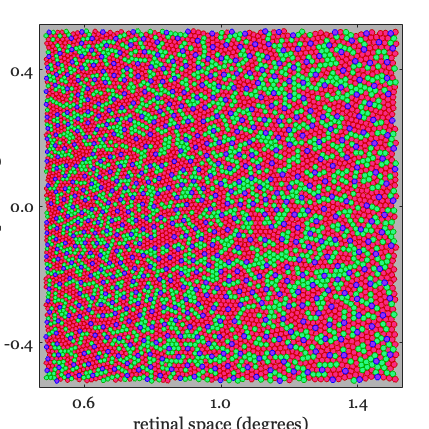

vParms = cm.visualize();    % Visualize the mosaic

## Line plots

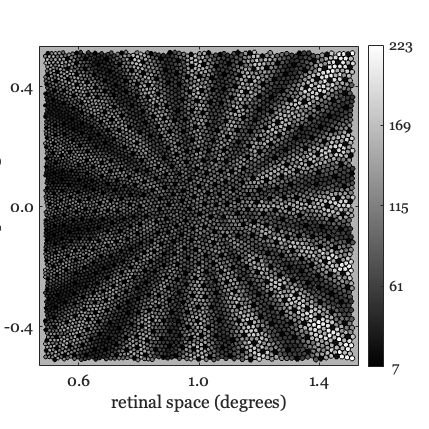

% Create an image of the excitations
cm.plot('excitations',allE);

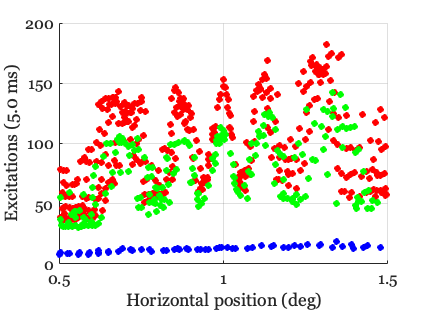


% Plot the excitations along a horizontal line
cm.plot('excitations horizontal line',allE, 'y deg',0.3);

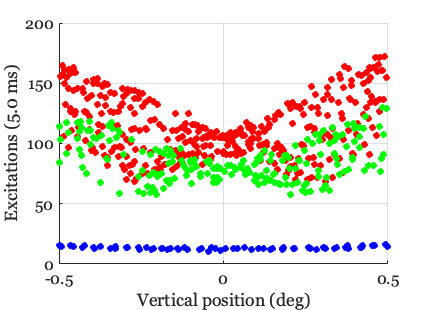

cm.plot('excitations vertical line',allE, 'x deg',1);

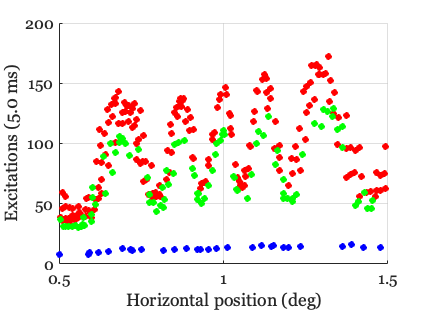


% Set the thickness of the horizontal line
cm.plot('excitations horizontal line',allE, 'y deg',0.3,'thickness',0.05);

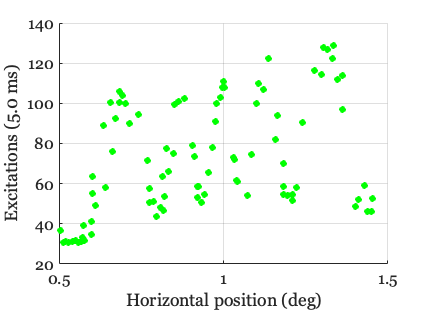

cm.plot('excitations horizontal line',allE, 'y deg',0.3,'thickness',0.05, 'conetype','m');

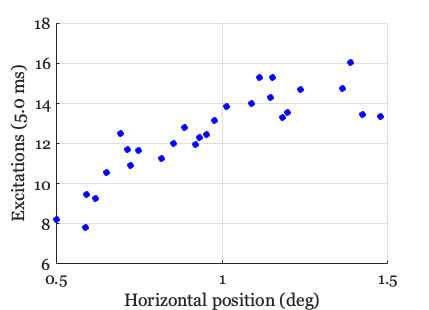

cm.plot('excitations horizontal line',allE, 'y deg',0.3,'thickness',0.05, 'conetype','s');

## Such a thick line regionOfInterest (ROI) superimposed on the activations

For help on ROIs, use this: 

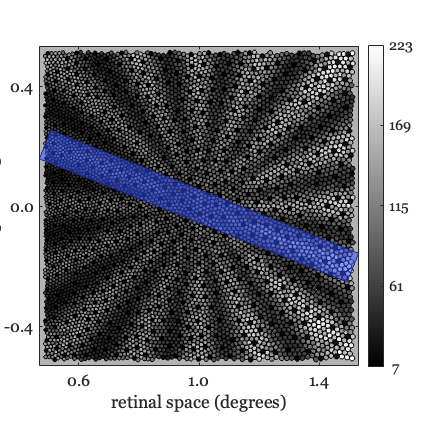

roiLine = regionOfInterest('shape', 'line', ...
    'from', [.5 0.2], 'to', [1.5,-0.2], ...
    'thickness', 0.1);

% Show the ROI on top of the activations
cm.plot('roi',allE, 'roi',roiLine);

## Elliptical ROI

We can create elliptical (or circular) ROIs.  I believe that at present NC uses majorAxisDiameter to be y by default and minorAxisDiameter to be x.  I don't yet understand the code.  We plan to allow setting the orientation as well.

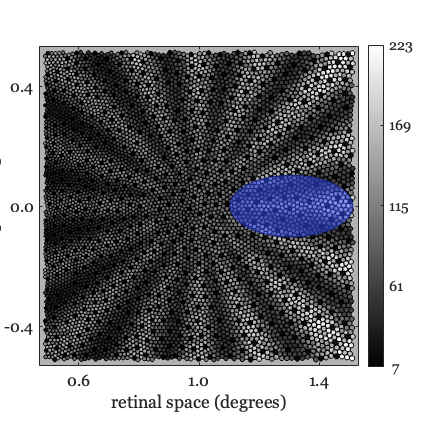

roiCircle = regionOfInterest('shape','ellipse',...
    'center',[1.3 0],...
    'majorAxisDiameter',0.2,...
    'minorAxisDiameter',0.4);

cm.plot('roi',allE, 'roi',roiCircle);

## Plot the activations along a line ROI

This differs from excitations horizontal line because the line can be any direction.

You can also select to plot just one or all of the different cone types.

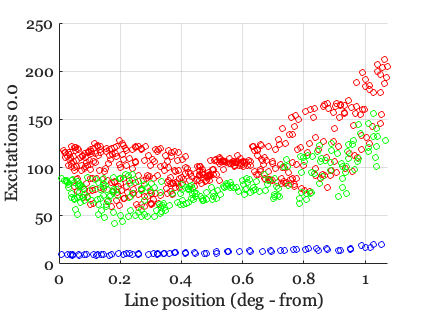

cm.plot('excitations roi',allE, 'roi',roiLine);

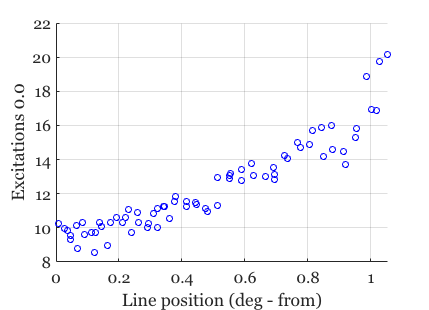

cm.plot('excitations roi',allE, 'cone type','s','roi',roiLine);